# Supervised Learning - Week 3 / Part 3

## Simplified Cost Function

In the previous file we saw the loss function and the cost function for the logistic regression. In this file we will see a simpler way to write the loss and cost functions for a logistic regression task. Therefore, the implementation will be simpler when we need to implement logistic regression using gradient descent (GD).

As a reminder, the following is the loss function for the logistic regression,


$$L\left( y^{(i)}, f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right) = 
\left\{
    \begin{array}{lr}
        -\log\left( f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 1  \\
        -\log\left( 1 - f_{\mathbf{w},b}( \mathbf{x}^{(i)}) \right), & \text{if } y^{(i)} = 0
    \end{array}$$


Since $y$ can only take the values 0 or 1 and nothing else, we will be able to come up with a simpler expression. We can write the loss function as follows:


$$L\left( y^{(i)}, f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) = -(1-y^{(i)}) \log \left( 1 - f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) - y^{(i)}\log \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right)$$


Using the simplified loss function definition above, we can write a simplified cost function expression as follows:


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


An important question this point is that "Why did we chose this particular loss function, where there are plenty of other alternative loss functions out there?"

This particular loss function is derived using **maximum likelihood estimation (MLE)**. Also, this cost function has good properties of being convex, which is crucial for the GD implementation.

 In the upcoing lab, we will see how the logistic regression cost function is implemented. Moreober, we will also see that how two different selection of a parameter leads to two different loss functions.

## Optional Lab: Cost Function for Logistic Regression

Let's use the data set that we used while working on the decision boundaries

X_train = [0.5, 1.5; 1, 1; 1.5, 0.5; 3, 0.5; 2, 2; 1, 2.5];
y_train = [0, 0, 0, 1, 1, 1];

Let's plot the data set

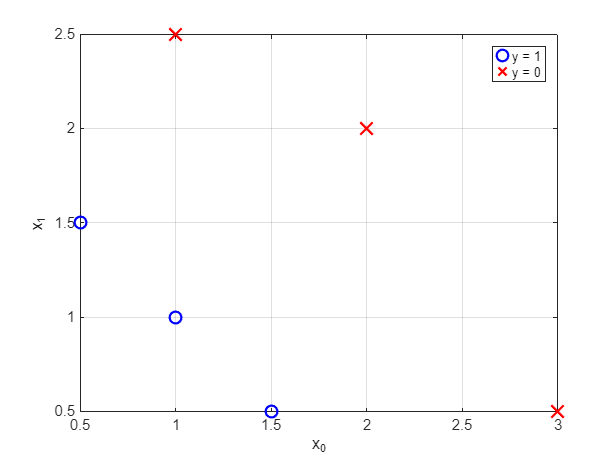

% Plot data set
figure;
hBinaryScatter(X_train, y_train, {'o','x'}, {'b','r'}, 8);
legend('y = 1','','','y = 0','','','Location','northeast');
xlabel('x_0');
ylabel('x_1');
grid on;

### Cost Function


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


where $m$ is the number of training samples. Moreover,

$ f_{\mathbf{w},b}(\mathbf{x}^{(i)}) = g(z^{(i)}) = g(\mathbf{x}^{(i)}\mathbf{w}+b)$, where $g(\mathbf{x}^{(i)}\mathbf{w}+b) = \frac{1}{1 + e^{-\mathbf{x}^{(i)}\mathbf{w}+b}}$

function J = computeLogisticRegressionCost(X, y, w, b)
    % Arguments:
    % X (m,n) : Data, m examples with n features
    % y (m,1) : Target values
    % w (n,1) : model weights

Cost (J): 0.3668667864


    % b (1,1) : model bias

Squared Error (actual vs expected): 1.2325952E-32


    m = size(X,1);
    fwb = zeros(m,1);
    J_tmp = 0;
    
    for i = 1:m
        z = X(i,:)*w + b;
        fwb(i) = ( 1/(1+exp(-z)) );
        
        J_tmp = J_tmp + ( (1-y(i))*log(1-fwb(i)) + y(i)*log(fwb(i)) );
    end
    J = -(1/m)*J_tmp;
end

Test the implemented of the cost function, (**Expected output**: 0.3668667864055175)

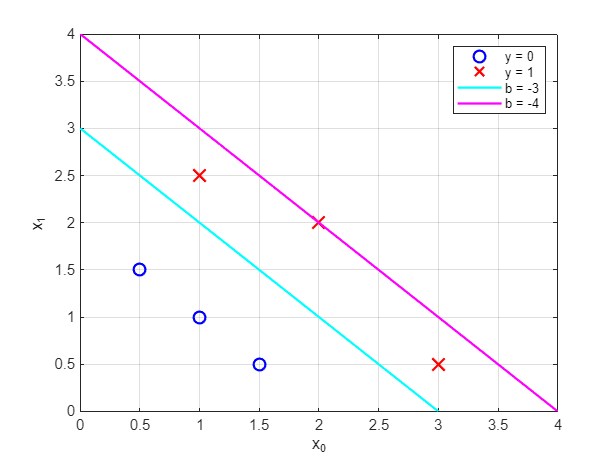

expected_val = 0.3668667864055175;
w_tmp = [1 1].';
b_tmp = -3;
J = computeLogisticRegressionCost(X_train, y_train, w_tmp, b_tmp);
fprintf('Cost (J): %.10G\n', J);

fprintf('Squared Error (actual vs expected): %.8G\n', (J-expected_val)^2);

### Example

Now since we tested the logistic regression cost function, we can examine the cost function output for different $\mathbf{w}$ and $b$.

Let's plot the decision boundary for $w_0=1$, $w_1=1$, $b = -3$ (shown in magenta), $x_0 + x_1 - 3 = 0$

 and $w_0=1$, $w_1=1$, $b = -4$ (shown in cyan), $x_0 + x_1 - 4 = 0$.

x0 = linspace(0,4);


Cost for b = -3 (J): 0.3668667864


figure;
hBinaryScatter(X_train, y_train, {'o','x'}, {'b','r'}, 8);

Cost for b = -4 (J): 0.5036808637


hold on;
plot(x0,3-x0,'c','LineWidth',1.5);
plot(x0,4-x0,'m','LineWidth',1.5);
legend('y = 0','','','y = 1','','','b = -3','b = -4','Location','northeast');
xlabel('x_0');
ylabel('x_1');
grid on;
hold off;
ylim([0 4])

We can see from the above plot that $b=-4$ is a worse model for training data. Let's examine if the loss function reflects this characteristics.

J1 = computeLogisticRegressionCost(X_train, y_train, [1 1].', -3);
fprintf('Cost for b = -3 (J): %.10G\n', J1);
J2 = computeLogisticRegressionCost(X_train, y_train, [1 1].', -4);
fprintf('Cost for b = -4 (J): %.10G\n', J2);

We can see from the above results that the cost function behaves as expected, where the cost function for $b = -4$ case is higher than $b = -3$ case.

## Gradient Descent Implementation

We will take a look at how to find a good choice for the parameters $\mathbf{w}$ and $b$ that minimizes the cost function $J(\mathbf{w},b)$ using gradient descent (GD). The objective could be summarized as follows:

- Find the parameters $\mathbf{w}$, $b$

- Given new input ($\mathbf{x}^{(i)}$) that outputs $f_{\mathbf{w},b}(\mathbf{x}) = \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}$

- Then, model make a prediction $P(y=1 ~ | ~ \mathbf{x}^{(i)}~;~\mathbf{w},b)$

- In the mean time, the algorithm will try to minimizing the cost function ($J(\mathbf{w},b)$) to increase the prediction quality.


$$J(\mathbf{w},b) = \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) = -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)$$


- If we want to minimize the cost function $J(\mathbf{w},b)$, we will use the usual GD algorithm:

repeat {


$$w_j = w_j - \alpha\frac{\partial J(\mathbf{w},b)}{\partial w_j} ~,$$



$$b = b - \alpha\frac{\partial J(\mathbf{w},b)}{\partial b}$$


}

where $j \in \{1,2,\cdots,n\}$ and $n$ represents the number of features. You repetively update the parameters $\mathbf{w}$ and $b$ based on the derivative of the cost function, $J(\mathbf{w},b)$, with respect to the parameters. Let's calculate the terms $\frac{\partial J(\mathbf{w},b)}{\partial w_j}$ and $\frac{\partial J(\mathbf{w},b)}{\partial b}$ to implement the GD algorithm.

- Let's start with $\frac{\partial J(\mathbf{w},b)}{\partial w_j}$

### Partial derivative of the cost function w.r.t weights


$$\frac{\partial J(\mathbf{w},b)}{\partial w_j}

= \frac{\partial}{\partial w_j} \bigg( -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg) \\

= -\frac{1}{m} \sum_{i=1}^{m} \bigg( \frac{\partial}{\partial w_j} \left( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \right) + \frac{\partial}{\partial w_j} \left( \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \right) \bigg).$$


- Let's focus on the first term of the sum,

 
$$\frac{\partial}{\partial w_j} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)}  \frac{\partial}{\partial w_j} \bigg( \log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)} \cdot \frac{\frac{\partial}{\partial w_j}f_{\mathbf{w},b}(\mathbf{x}^{(i)})}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \quad ,$$


where we know that

$\frac{\partial}{\partial w_j} \bigg( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \bigg) 

= x_j^{(i)} \cdot f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big)$, where the proof is provided in Appendix 1.

Hence,

 
$$\frac{\partial}{\partial w_j} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg)

= y^{(i)} \bigg( \frac{\frac{\partial}{\partial w_j}f_{\mathbf{w},b}(\mathbf{x}^{(i)})}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \bigg)

=  y^{(i)} \bigg( \frac{x_j^{(i)} \cdot f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big)}{f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \bigg)

= y^{(i)} \bigg( x_j^{(i)} \cdot \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big) \bigg) \quad \#$$


- Let's focus on the second term of the sum. Based on the product rule and derivative of a $\log()$ function,

$\frac{d}{dx} \left( u \cdot v \right) = \frac{du}{dx} \cdot v + u \cdot \frac{dv}{dx}$ and

 
$$\frac{d}{dx}\log_{a} f(x) = \frac{1}{f(x)\ln(a)} \cdot \left( \frac{d}{dx}f(x) \right)$$


We can obtain the following,


$$\frac{\partial}{\partial w_j} \bigg( \left(1-y^{(i)}\right) \log\left( 1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) 

= 0 \cdot  \log\left( 1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left(1-y^{(i)}\right) \cdot  \bigg( \frac{1}{ 1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) } \cdot \frac{d}{dw_j} \left( 1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \\

= \frac{1-y^{(i)}}{1-f_{\mathbf{w},b}(\mathbf{x}^{(i)})} \cdot \bigg( -x_j^{(i)} \cdot f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big) \bigg)

=  \left( y^{(i)}-1 \right) \cdot x_j^{(i)} \cdot f_{\mathbf{w},b}(\mathbf{x}^{(i)})  \quad \#
$$


- If we combine the parts 1 and 2,


$$\frac{\partial J(\mathbf{w},b)}{\partial w_j} = -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)} \cdot x_j^{(i)} \cdot \big( 1-f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) \big) + 
 \left( y^{(i)}-1 \right) \cdot x_j^{(i)} \cdot f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \bigg) \\

= -\frac{1}{m}\sum_{i=1}^{m} \bigg( y^{(i)}x_j^{(i)} - y^{(i)}x_j^{(i)}f_{\mathbf{w},b}(\mathbf{x}^{(i)}) + y^{(i)}x_j^{(i)}f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - x_j^{(i)}f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \bigg)$$


Finally,


$$\frac{\partial J(\mathbf{w},b)}{\partial w_j} =  \frac{1}{m}\sum_{i=1}^{m} \bigg( x_j^{(i)} \left(f_{\mathbf{w},b}(\mathbf{x}^{(i)}) -  y^{(i)} \right) \bigg) \quad \#$$


In other words,


$$\frac{\partial J(\mathbf{w},b)}{\partial w_j} =  \frac{1}{m}\sum_{i=1}^{m} \bigg( x_j^{(i)} \cdot e^{(i)} \bigg) ~ ,$$


where $e^{(i)}$ represents the error term for the $i^\text{th}$ sample, $e^{(i)} = f_{\mathbf{w},b}(\mathbf{x}^{(i)}) -  y^{(i)}$.

### Partial derivative of the cost function w.r.t bias

Now, let's also look at the term $\frac{\partial J(\mathbf{w},b)}{\partial b}$


$$\frac{\partial J(\mathbf{w},b)}{\partial b}

= \frac{\partial}{\partial b} \bigg( -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg) \\

= -\frac{1}{m} \sum_{i=1}^{m} \bigg( \frac{\partial}{\partial b} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) +

\frac{\partial}{\partial b} \bigg(  \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg)$$


- Let's focus on the first term,


$$\frac{\partial}{\partial b} \bigg( y^{(i)}\log(f_{\mathbf{w},b}( \mathbf{x}^{(i)} )) \bigg)

= 0 \cdot \log(f_{\mathbf{w},b}( \mathbf{x}^{(i)} )) + y^{(i)} \cdot \frac{\frac{\partial}{\partial b} \left( f_{\mathbf{w},b}( \mathbf{x}^{(i)} ) \right)}{f_{\mathbf{w},b}( \mathbf{x}^{(i)} )} \\

= \frac{y^{(i)}}{f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right)} \cdot \bigg(  f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \cdot \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \bigg)

= y^{(i)} \cdot \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big)$$


- Now, we can focus on the second term,


$$\frac{\partial}{\partial b} \bigg(  \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg) 

= 0 \cdot \log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) + (1-y^{(i)}) \cdot \bigg( \frac{1}{1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) } \cdot \frac{\partial}{\partial b} \left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \\

= \frac{\left(  1 - y^{(i)} \right)}{\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right)} \cdot \bigg(  -f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \cdot \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \bigg) 

= \left( y^{(i)} - 1 \right) \cdot f_{\mathbf{w},b}(\mathbf{x}^{(i)})$$


- If we combine both parts,


$$\frac{\partial J(\mathbf{w},b)}{\partial b}

= -\frac{1}{m} \sum_{i=1}^{m} \bigg( \frac{\partial}{\partial b} \bigg( y^{(i)}\log\left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) +

\frac{\partial}{\partial b} \bigg(  \left( 1-y^{(i)} \right)\log\left(1-f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) \bigg) \\

= -\frac{1}{m} \sum_{i=1}^{m} \bigg( y^{(i)} \cdot \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) + \left( y^{(i)} - 1 \right) \cdot f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \bigg)$$


Finally,


$$\frac{\partial J(\mathbf{w},b)}{\partial b}

=  \frac{1}{m} \sum_{i=1}^{m} \bigg( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \bigg) \quad \#$$


In other words,


$$\frac{\partial J(\mathbf{w},b)}{\partial b}

=  \frac{1}{m} \sum_{i=1}^{m} e^{(i)} ~,$$
 

where $e^{(i)}$ represents the error term for the $i^\text{th}$ sample, $e^{(i)} = f_{\mathbf{w},b}(\mathbf{x}^{(i)}) -  y^{(i)}$.

**Please note that similar to the linear regression task, the way to update the parameters has to be simultaneous in order not to affect the gradients. **

- Simultaneous update means that we would calculate the right hand side of each expression, $\frac{\partial J(\mathbf{w}, b)}{\partial w_j} $ and $\frac{\partial J(\mathbf{w}, b)}{\partial b} $ first. 

- And then simultaneously calculate and overwrite, $w_j = w_j - \alpha\frac{\partial J(\mathbf{w},b)}{\partial w_j}$ and $b = b - \alpha\frac{\partial J(\mathbf{w},b)}{\partial b}$.

Consequently the gradient descent (GD) for logistic regression task becomes,

- Randomly initialize the parameters: $\mathbf{w}$, and $b$.

- Repeat the following expression until the condition is satisfied; (i) Minimum error has been reached, or (ii) maximum number of iterations has been reached.


$$w_j = w_j - \alpha\frac{1}{m}\sum_{i=1}^{m} \bigg( \left(f_{\mathbf{w},b}(\mathbf{x}^{(i)}) -  y^{(i)} \right) \cdot x_j^{(i)}  \bigg) \quad (1)$$



$$b = b - \alpha \frac{1}{m} \sum_{i=1}^{m} \bigg( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \bigg) \quad (2)$$


**Now, one interesting thing to note here is that the GD algorithm for the linear regression task was also the same.**


$$w_j 

= w_j - \alpha\frac{\partial}{\partial w_j}J(\mathbf{w},b)

=  w_j - \alpha \left( \frac{1}{m}\sum_{i=1}^{m} \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) - y^{(i)} \right) \cdot
x_j^{(i)} \right)  

\quad (3)$$



$$b 

= b - \alpha\frac{\partial}{\partial b}J(\mathbf{w},b)

= b - \alpha \left( \frac{1}{m} \sum_{i=1}^{m} \left( f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) - y^{(i)}  \right) \right)

\quad (4)$$
 

for $i \in \{ 1,2,\cdots,m\}$ and $j \in \{ 1,2,\cdots, n\}$. 

Obviously, the definition of the function $f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right)$ is different for the linear and logistic regression tasks:

- **Linear regression:** $f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) = \mathbf{x}^{(i)} \mathbf{w} +b$

- **Logistic regression:** $f_{\mathbf{w},b}\left( \mathbf{x}^{(i)} \right) = \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}$

Although the general GD algorithm is the same in the high level, the output function in each task is different from each other.

## Optional Lab: Gradient Descent Implementation for Logistic Regression

In this lab we will:

- Implement the gradient descent (GD) for logistic regression.

- Explore GD on a familiar dataset

### Data set

Let's start with the same two feature data set used in the decision boundary lab.

X_train_2 = [0.5 1.5; 1 1; 1.5 0.5; 3 0.5; 2 2; 1 2.5];
y_train_2 = [0; 0; 0; 1; 1; 1];

Let's plot this data using the helper function `hBinaryScatter`,

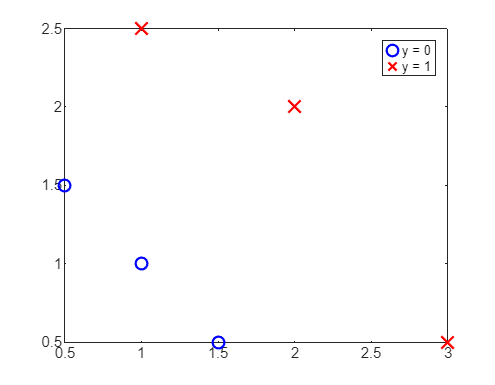

f = figure;

hBinaryScatter(X_train_2, y_train_2, {'o', 'x'}, {'b', 'r'}, 8);
f.Position = [0 0 450 350];
legend('y = 0','','','y = 1')

### Logistic Gradient Descent

- 
$$w_j 

= w_j - \alpha\frac{\partial}{\partial w_j}J(\mathbf{w},b)

= w_j - \alpha\frac{1}{m}\sum_{i=1}^{m} \left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} -  y^{(i)} \right) \cdot x_j^{(i)} 

=  w_j - \alpha\frac{1}{m}\sum_{i=1}^{m} \bigg( e^{(i)} \cdot x_j^{(i)} \bigg)$$


- 
$$b 

= b - \alpha\frac{\partial}{\partial b}J(\mathbf{w},b)

= b - \alpha \frac{1}{m} \sum_{i=1}^{m} \bigg( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} - y^{(i)} \bigg) 

= b - \alpha \frac{1}{m} \sum_{i=1}^{m} e^{(i)}$$


for $i \in \{ 1,2,\cdots,m\}$ and $j \in \{ 1,2,\cdots, n\}$, where $m$ and $n$ are the number of samples and number of features, respectively. 

Similarly, the cost function is calculated as follows:


$$J(\mathbf{w},b) 

= \frac{1}{m} \sum_{i=1}^{m} L \left( f_{\mathbf{w},b} (\mathbf{x}^{(i)}), y^{(i)}  \right) 

= \frac{1}{m} \sum_{i=1}^{m} \bigg( - y^{(i)}\log \left( f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) - (1-y^{(i)}) \log \left( 1 - f_{\mathbf{w},b}(\mathbf{x}^{(i)}) \right) \bigg) ~,$$


where $f_{\mathbf{w},b}(\mathbf{x}) = \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} ~ .$

w_init = [2; 3];
b_init = 1;
[J_vec, w, b] = hLogisticRegression(X_train_2, y_train_2, w_init, b_init, LearnRate=0.1, MaxIter=1);

Iteration: 0 -- w_vec: [ 1.9502      2.9501 ] | b: 0.9501 | Cost (J): 3.00138402 
----------
Termination: Maximum iterations reached.


As we made sure that the gradient descent (GD) with logistic regression works for a small scale example, we can do a full training and check the results as follows.

w_init = [0; 0]; % zero initialization
b_init = 0; % zero initialization
alpha = 0.1;
iters = 10000;
[J_vec, w, b] = hLogisticRegression(X_train_2, y_train_2, w_init, b_init, LearnRate=alpha, MaxIter=iters);

Iteration: 0 -- w_vec: [ 0.025    0.016667 ] | b: -0.0000 | Cost (J): 0.69314718 
Iteration: 1000 -- w_vec: [ 2.3057      2.0774 ] | b: -5.9110 | Cost (J): 0.15923356 
Iteration: 2000 -- w_vec: [ 3.1551      2.9402 ] | b: -8.3115 | Cost (J): 0.08464110 
Iteration: 3000 -- w_vec: [ 3.6809       3.471 ] | b: -9.7823 | Cost (J): 0.05707200 
Iteration: 4000 -- w_vec: [ 4.0602      3.8528 ] | b: -10.8386 | Cost (J): 0.04291828 
Iteration: 5000 -- w_vec: [ 4.3565      4.1505 ] | b: -11.6615 | Cost (J): 0.03434535 
Iteration: 6000 -- w_vec: [ 4.5993      4.3943 ] | b: -12.3350 | Cost (J): 0.02860858 
Iteration: 7000 -- w_vec: [ 4.8049      4.6006 ] | b: -12.9047 | Cost (J): 0.02450509 
Iteration: 8000 -- w_vec: [ 4.9832      4.7795 ] | b: -13.3983 | Cost (J): 0.02142640 
Iteration: 9000 -- w_vec: [ 5.1406      4.9372 ] | b: -13.8335 | Cost (J): 0.01903226 
Iteration: 10000 -- w_vec: [ 5.2814      5.0783 ] | b: -14.2228 | Cost (J): 0.01711777 
----------
Termination: Maximum iterations reached

### **Let's now plot the results of the gradient descent**

In order to do the prediction with the parameters we've found, we need a threshold to make a decision such that:


$$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } f_{\mathbf{w},b}(\mathbf{x}) \geq \text{Threshold}  \\
        0, & \text{if } f_{\mathbf{w},b}(\mathbf{x}) < \text{Threshold}
    \end{array}$$


where the threshold is chosen to be `0.5` since function of interest (the curve that we fit into our data) is "S-shaped" curve called **sigmoid function**. We can also express the above expression as follows:

$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } g(z) \geq 0.5  \\
        0, & \text{if } g(z) < 0.5
    \end{array}$    .

We can look at the sigmoid function plot and infer the following:


$$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } z \geq 0  \\
        0, & \text{if } z < 0
    \end{array}$$
 

where $z =  \mathbf{x}\mathbf{w} + b$,


$$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } \mathbf{x}\mathbf{w} + b \geq 0  \\
        0, & \text{if } \mathbf{x}\mathbf{w} + b < 0
    \end{array}$$
 

In order to visualize the above expression (decision boundary), we need to plot the line $\mathbf{x}\mathbf{w} + b = w_1x_1 + w_2x_2 +b = 0$.

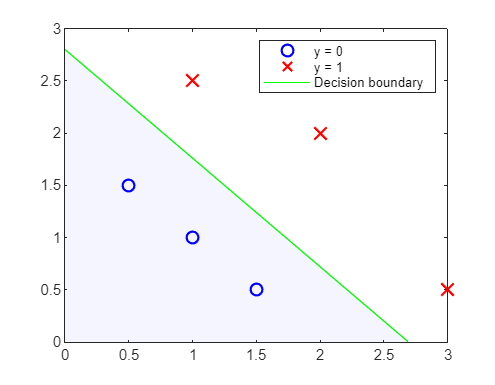

f = figure;

% Plot the data
hBinaryScatter(X_train_2, y_train_2, {'o', 'x'}, {'b', 'r'}, 8);
% Plot the decision boundary
hold on
line([0 -b/w(1)],[-b/w(2) 0],'Color','green')
area([0 -b/w(1)],[-b/w(2) 0],'EdgeColor','green','FaceColor','blue','FaceAlpha',0.04)
hold off
f.Position = [0 0 450 350];
legend('y = 0','','','y = 1','','','Decision boundary')

Note that in the above figure the decision boundary is the line at which the probability of sample being a member of class 1 is 0.5

- 
$$f_{\mathbf{w},b}(x) = P(y=1 ~|~ \mathbf{x};\mathbf{w},b) = 0.5$$


### Another Data Set

Let's now return to a one-dimensional data set. With just two parameters ($\mathbf{w}$ and $b$), it is possible to plot the cost function using a contour plot get a better idea of what gradient descent does.

X_train_3 = [0 1 2 3 4 5].';
y_train_3 = [0 0 0 1 1 1].';

Let's plot the data points.

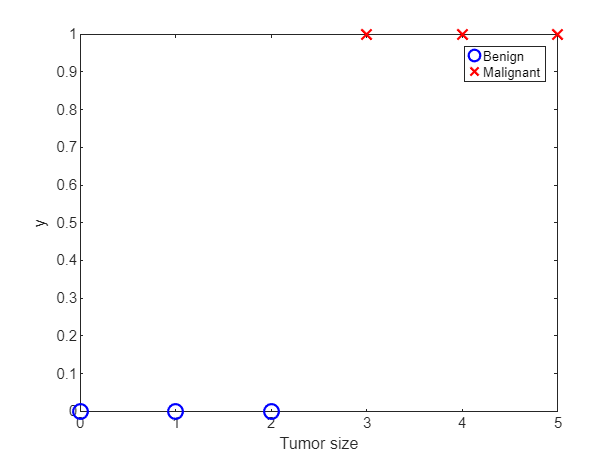

figure;
hBinaryScatter(X_train_3, y_train_3, {'o','x'},{'b','r'}, 10)
xlabel('Tumor size')
ylabel('y')
legend('Benign','','','Malignant','','')

Let's visualize the gradient descent per each step, where we can track the linear regression, logistic regression, and cost function curves

----------
Termination: Maximum iterations reached.


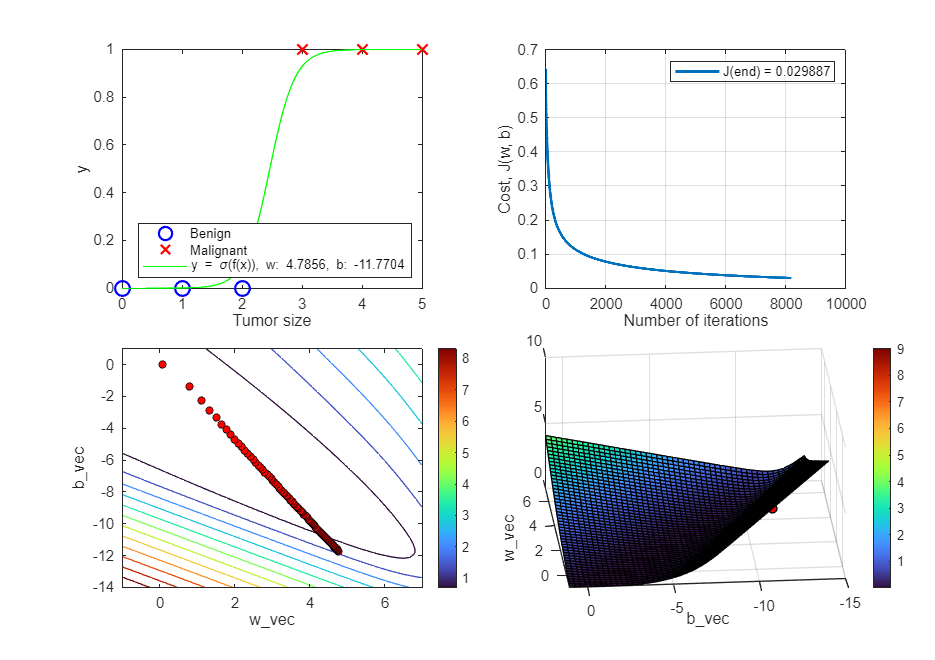

iters = 8185; % number of training iterations

w_vec_range = -1:0.1:7;
b_range = -14:0.1:1;
alpha = 0.1;
w_init = 0;
b_init = 0;
[J_vec, w_vec, b_vec] = hInteractiveLogisticRegression(X_train_3, y_train_3, w_init, b_init, LearnRate=alpha, MaxIter=iters, Verbose=false);

fprintf('Final values - Cost: %.4f | w: %.4f | b: %.4f\n ', J_vec(end), w_vec(end), b_vec(end));

Final values - Cost: 0.0299 | w: 4.7856 | b: -11.7704
 

## Appendix

### 1 - Derivative of the sigmoid function with respect to the weights and a bias

#### Weights

As a direct consequence of the Appendix 2. We can infer the following:


$$\frac{\partial}{\partial w_j}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right) 

= \frac{\partial}{\partial w_j}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right)

= \frac{\partial}{\partial w_j}\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-1} \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \frac{\partial}{\partial w_j}\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \left( \frac{\partial}{\partial w_j}\big( -(\mathbf{x}^{(i)}\mathbf{w}+b) \big) \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right) \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \cdot \bigg( \frac{\partial}{\partial w_j}\big( -\left( x_1^{(i)}w_1+\cdots+x_j^{(i)}w_j+\cdots+x_n^{(i)}w_n + b \right) \big) \bigg) \\

=  -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}  \cdot \left( -x_j^{(i)} \right) \\

= \left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \left( e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} +1-1\right)  \cdot \left( x_j^{(i)} \right) \\

=  x_j^{(i)}\frac{\left( e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} +1-1\right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}}

=  x_j^{(i)}\frac{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}-1\right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}}

= x_j^{(i)}\frac{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}} - x_j^{(i)}\frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{2}} \quad ,$$


Therefore,


$$\frac{\partial}{\partial w_j}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right)

= \frac{\partial}{\partial w_j}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right) \\

= \frac{x_j^{(i)}}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}\right)} \bigg( 1 - \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}\right)} \bigg)

=   x_j^{(i)} \cdot f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \cdot \big( 1- f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \quad \#$$


#### Bias


$$\frac{\partial}{\partial b}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right)

= \frac{\partial}{\partial b}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right)

= \frac{\partial}{\partial b}\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-1} \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \frac{\partial}{\partial b} \left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot \bigg( \frac{\partial}{\partial b} \big( -(\mathbf{x}^{(i)}\mathbf{w}+b) \big) \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \bigg) \\

= -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \cdot \bigg( \frac{\partial}{\partial b} \big( -\left( x_1^{(i)}w_1 + x_2^{(i)}w_2 + \cdots + x_n^{(i)}w_n + b \right) \big) \bigg) \\

=  -\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \cdot \left( -1 \right)

= \left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^{-2} \cdot e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \quad ,$$


Therefore,


$$\frac{\partial}{\partial b}\left( f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \right)

= \frac{\partial}{\partial b}\left( \frac{1}{1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}} \right)

= \frac{e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)^2} \\

= \frac{e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \cdot  \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} = \frac{e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}+1-1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \cdot \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \\

= \bigg( \frac{1 + e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)}}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} - \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \bigg) \cdot \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \\

= \bigg( 1 -  \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \bigg)  \cdot \frac{1}{\left( 1+e^{-(\mathbf{x}^{(i)}\mathbf{w}+b)} \right)} \\

= \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \cdot  f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) 

=  f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \cdot \big( 1 - f_{\mathbf{w},b} \left( \mathbf{x}^{(i)} \right) \big) \quad \#$$


### 2 - Derivative of the sigmoid function

In AI/ML area, the sigmoid function is defined as $\sigma(x) = \frac{1}{1+e^{-x}}$. Derivative of the sigmoid function is crucial for computing the updating the parameters in GD algorithm. Accordingly, in this section we will derive the derivative expression of the sigmoid function.


$$\frac{\text{d}}{\text{d}x}\sigma(x) =  \frac{\text{d}}{\text{d}x} \frac{1}{\left(1+e^{-x}\right)} = \frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right)^{-1} = -\left( 1+e^{-x} \right)^{-2}\frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right) \\
=  -\left( 1+e^{-x} \right)^{-2}\frac{\text{d}}{\text{d}x} \left( 1+e^{-x} \right) = -\left( 1+e^{-x} \right)^{-2}\left( -e^{-x} \right) \quad ,$$


Therefore,


$$\frac{\text{d}}{\text{d}x}\sigma(x) = -\left( 1+e^{-x} \right)^{-2}\left( -e^{-x} \right) = \left( 1+e^{-x} \right)^{-2}\left( e^{-x} +1-1 \right) = \frac{\left(1+e^{-x}\right)-1}{ \left( 1+e^{-x} \right)^{2} } \\
= \frac{1}{ \left( 1+e^{-x} \right)}  - \frac{1}{\left( 1+e^{-x} \right)^{2}} = \frac{1}{ \left( 1+e^{-x} \right)} \bigg( 1-\frac{1}{\left( 1+e^{-x} \right)} \bigg) \quad ,$$


Finally,


$$\frac{\text{d}}{\text{d}x}\sigma(x) = \sigma(x) \big( 1-\sigma(x) \big) \quad \#$$
